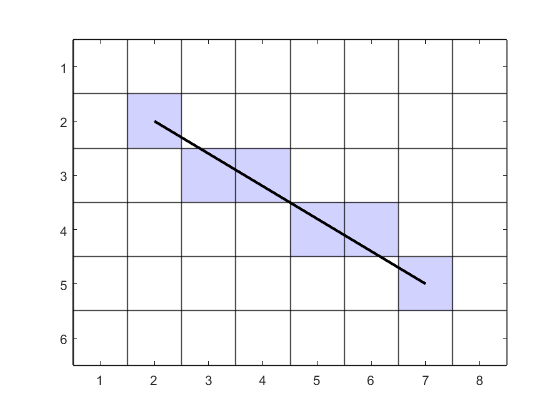

clear

% Raster parameters
Nx = 8;
Ny = 6;

% Line coordinates and colour
x0 = 2;
y0 = 2;
x1 = 7;
y1 = 5;
blue = [210, 210, 255];

% Initialise raster array and calculate pixel co-ordinates
img = uint8(255 * ones(Ny, Nx, 3));

% Draw line
img = drawline(img, x0, y0, x1, y1, blue);

image(img)
hold on
for row = 1 : 1 : Nx
    xline(row-0.5, Color='k', LineWidth=1)
    yline(row-0.5, Color='k', LineWidth=1)
end
plot([x0, x1], [y0, y1], 'k', LineWidth=2)
hold off

xticks(1:Nx)
axis equal
axis([0.5, Nx+0.5, 0.5, Ny+0.5])
exportgraphics(gcf,'../images/bresenham_example_2.png','Resolution',300) 

function R = drawline(R, x0, y0, x1, y1, colour)

x = x0;
y = y0;
dx = abs(x1 - x0);
dy = abs(y1 - y0);
d = dx - dy;
xstep = sign(x1 - x0);
ystep = sign(y1 - y0);

while true
    R(y, x, :) = colour;
    if x == x1 && y == y1
        return
    end
    e = 2 * d;
    if e >= -dy
        x = x + xstep;
        d = d - dy;
    end
    if e <= dx
        y = y + ystep;
        d = d + dx;
    end
end

end